# **problem 2**

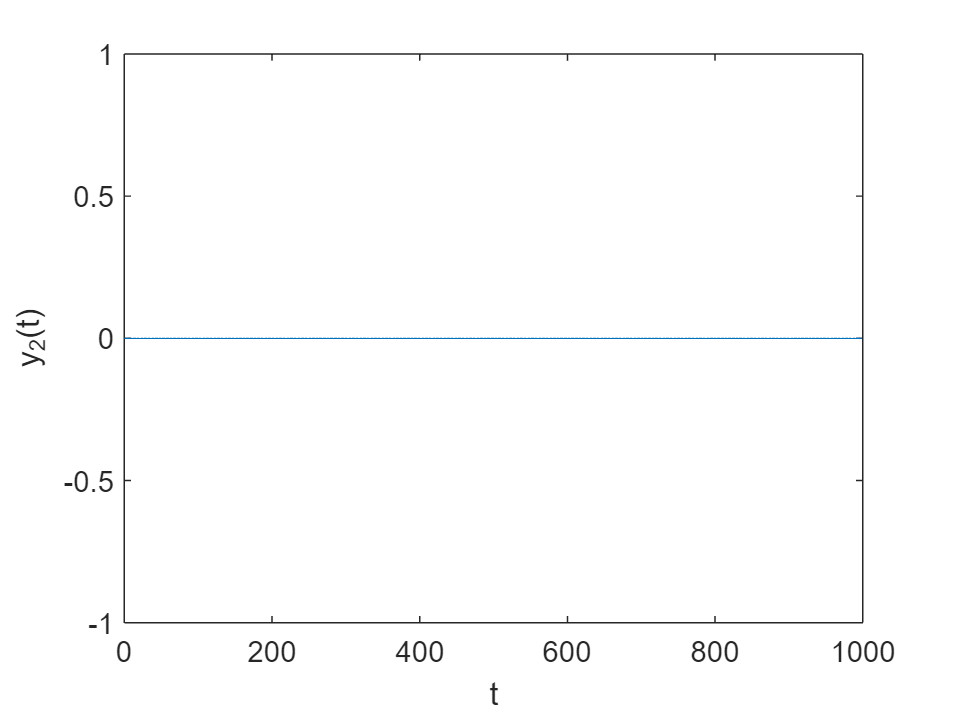

clc;
clear all;
t = 0:0.001:999;
y=zeros(1,999001);
tPrime = find_t_prime(x_2_func(t));
for i = 1:999001
    if (tPrime(i)>1) || (tPrime(i)<0)
        y(i) = 0;
    else
        y(i) = 1-tPrime(i);
    end
end
plot(t,y);
ylabel({'y_2(t)'});
xlabel({'t'});

function x_2 = x_2_func(t)
    x_2 = t.*exp(-t);
end
function t_prime = find_t_prime(x)
    t_prime = -log(x);
end